# Processing Data Samples from MRI

Reference - J. Appl. Phys. 105, 004904  (2009)

## Modelling of Moving Multilayered Dielectric Structures

The Material Properties table contains the properties of the material information

The Order is a sample order of the experiment

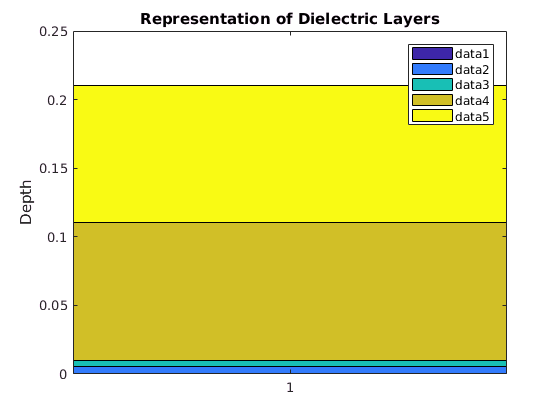

% Physics values
load('data/materials/MaterialData.mat');

X = 1;
Y = cell2mat(MaterialOrder.LayerThickness).';
[~, h] = size(Y);
Y(2, h) = 0;
Y = fliplr(Y);

% Draw a dielectric layer model from order
figure;
bar(Y,'stacked'); % stacks values in each row together
ax = axis;ax(2) = 1.4; %Change axis limit
axis(ax)
title('Representation of Dielectric Layers');
ylabel('Depth');
legend('show');

## Frequency Dependence on Individual Dielectric Structures

Finding the function of $\varepsilon$ with respect to the angular velocity using the cole-cole dispersions


$$\varepsilon \left(\omega \right)=\varepsilon_{\infty } +\sum_{m=1}^{n} \frac{\Delta \varepsilon_m }{1+{\left(j\omega \tau_m \right)}^{\left(1-\alpha_m \right)} }+\frac{\sigma_i }{j\omega \varepsilon_m }$$


where $\varepsilon$ permittivity, $\tau$ is time constant, $\omega$ is angular velocity, $\sigma$ is conductivity

w = linspace(1e9, 10e9);
t = 20 % Temperature

t = 20

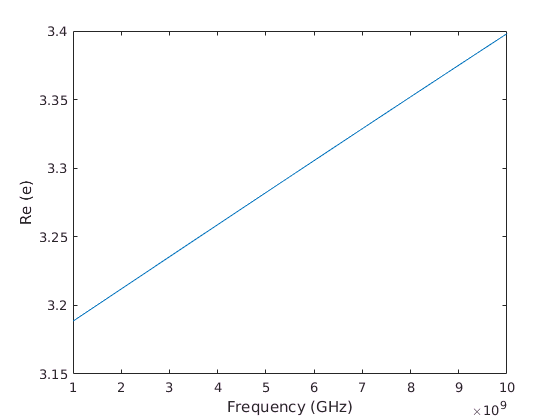

e_zero = 8.85418782e-12; % Permittivity of free space
figure

for mat = 2:2 %1:height(MaterialOrder)
    m = MaterialProperties(MaterialOrder{mat, 1}{1},:);
    p_inf = m.Permittivity_inf{1};
    p_zero = m.Permittivity_zero{1};
    c = m.Conductivity{1};
    t = m.TimeConstant{1};
    d = m.DebyeRelaxationFactor{1};
    
    y = p_inf + (p_zero - p_inf) ./ (1 + (1j * w * t) .^ (1 * d)) + c ./ (1j + w * e_zero);
    plot(w,y);
    hold on;
end